## 4.2 Numerical Approximation to the Continuous-Time Fourier Transform

A large class of signals can be represented using the continuous-time Fourier transform (CTFT) in Eq. (4.1). In this exercise you will use MATLAB to compute numerical approximations

to the CTFT integral, Eq. (4.2). By approximating the integral using a summation over closely spaced samples in **t**, you will be able to use the function **fft** to compute your

approximation very efficiently. The approximation you will use follows from the definition of the integral

                                                    
$$\int_{-\infty}^{\infty} x(t)e^{-j\omega t} dt = \lim_{\tau \to \infty} \sum_{n=\infty}^{\infty} x(n\tau )e^{-j\omega n\tau} \tau$$


For a large class of signals and for sufficiently small $\tau$, the sum on the right-hand side is a good approximation to the CTFT integral. If the signal $x(t)$ is equal to zero for $t<0$ and

 $t\ge T$,  then the approximation can be written 

                                                                                                                                                                                              (4.7)

                                                    
$$\int_{-\infty}^{\infty} x(t)e^{-j\omega t} dt =\int_{0}^{T} x(t)e^{-j\omega t} dt   \approx \lim_{\tau \to \infty} \sum_{n=0}^{N-1} x(n\tau )e^{-j\omega n\tau} \tau$$
                                                                                                   

where $T=N\tau$ and N is an integer. You can use the function **fft** to compute the sum in Eq. (4.7) for a discrete set of frequencies $\omega_k$. If the N samples $x(n\tau)$ are stored in the

vector **x** then the function call **X=tau*fft(x)** calculates

                                                                                                                                                                            (4.8)

                                                                
$$X(k+1) = \tau \sum_{n=0}^{N-1} x(n\tau)e^{-j\omega n \tau}, \ \ \ \ \ \ \ 0\le k\le N $$


                                                                                                                                                                            (4.9)

                                                                    
$$\approx X(j\omega_k)$$


where

                                                                                                                                                                             4.10()

                                                               
$$\omega_k = \left\{
        \begin{array}{ll}

      \frac{2\pi k}{N \tau}, &  0\le k \le \frac{N}{2}   \\

      \frac{2\pi k}{N \tau}- \frac{2\pi}{\tau} , &   \frac{N}{2}  +1\le k \le N  \\



 \end{array}
    \right.$$
    

and **N** is assumed to be even. For reasons of computational efficiency, **fft** returns the positive frequency samples before the negative frequency samples. To place the frequency

samples in ascending order, you can use the function **fftshift**. To store in **X** samples of $X(j\omega_k)$ordered such that $x(k+1)$ is the CTFT evaluated at  $-\pi/\tau +(2\pi k/N\tau)$ for  $0\le k \le N-1$   , use **X=fftshift(tau*fft(x)).**

For this exercise, you will approximate the CTFT of  $x(t)= e^{-2|t|}$ using the function **fft **and a truncated version of $x(t)$. You will see that for sufficiently small $\tau$, you can compute

an accurate numerical approximation to $X(j\omega)$.

**Basic Problems**

(a). Find an analytic expression for the CTFT of  $x(t)= e^{-2|t|}$. You may find it helpful to think of $x(t) = g(t) + g(-t)$, where $g(t) = e^{2t}u(t)$.

**4.2a Analysis**

Analytic expression for the CTFT of $x(t) $:

    
$$x(t) = g(t) + g(-t) =e^{-2t}u(t)+e^{2t}u(-t)$$


According to the Eq(4.2):

        
$$X(j\omega)=  

\int_{-\infty}^{0} e^{2t}e^{-j\omega t} dt\ +\ 

\int_{0}^{\infty} e^{-2t}e^{-j\omega t} dt =

\frac{1}{2+j\omega} +\frac{1}{2j\omega} = \frac{4}{4+\omega^2}$$


(b). Create a vector containing samples of the signal$ y(t) = x(t - 5) $ for $\tau = 0.01$ and **T = 10** over the range** t=[O:tau:T-tau]**. Since $x(t)$ is effectively zero for $|t| > 5$, you

can calculate the CTFT of the signal $ y(t) = x(t - 5) $  from the above analysis using $N = T/\tau.$ Your vector **y** should have length N.

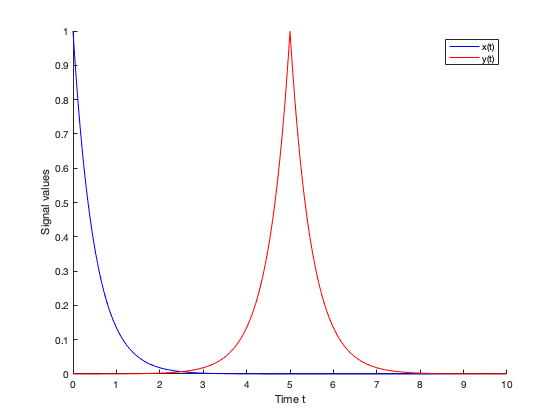

%4.2b Code

clf;
T=10;
tau=0.01;

%Because of abs(t)>5 I devide two pieces
%I didn't show the x(t) because it wasn't on the question and I add that
%signal and change shifting to the your way
t=0:tau:T-tau;

N=T/tau;
x=exp(-2*abs(t));
y=exp(-2*abs(t-5));


figure(1);
hold on
plot(t,x,'b');
plot(t,y,'r'); ylabel('Signal values'); xlabel('Time t');
legend('x(t)','y(t)');
hold off

(c). Calculate samples $Y(jwk)$ by typing **Y=fftshift(tau*fft(y))**.

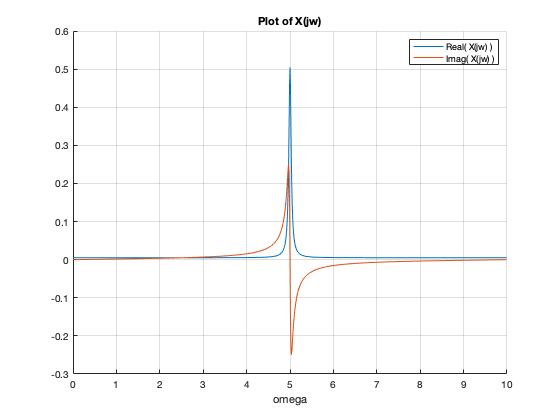

%4.2c Code
clf;
X=fftshift(tau*fft(x));
figure(2);
hold on
plot(t, real(X)); grid;
plot(t, imag(X));
title('Plot of X(jw)'); legend('Real( X(jw) )', 'Imag( X(jw) )'); xlabel('omega');

hold off

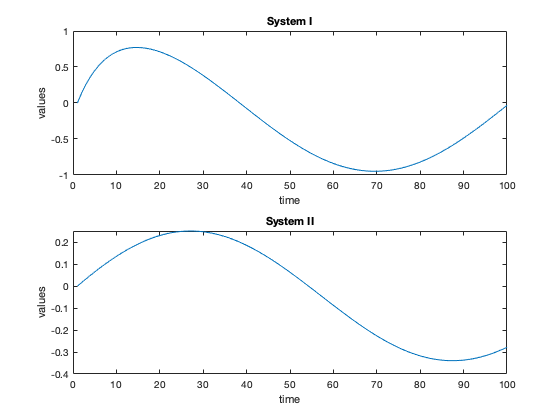

clf;

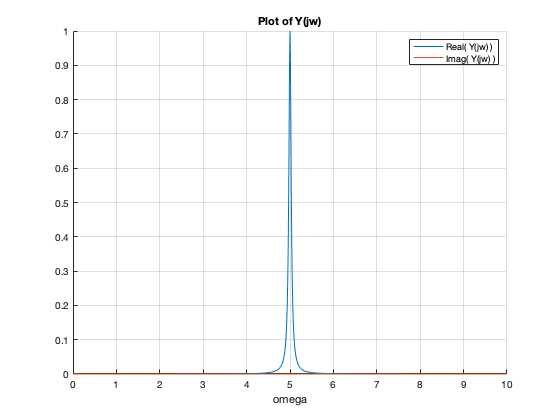

Y=fftshift(tau*fft(y));
figure(3);
hold on
plot(t, abs(real(Y)));   grid;
plot(t, imag(Y));
title('Plot of Y(jw)'); legend('Real( Y(jw) )', 'Imag( Y(jw) )'); xlabel('omega');
hold off

(d). Construct a vector **w** of frequency samples that correspond to the values stored in the vector **Y** as follows

**    >> w= -(pi/tau)+(0:N-1)*(2*pi/(N*tau));**

%4.2d Code
w = - ( pi/tau ) + ( 0:N-1 ) * ( 2*pi / (N*tau) )

w =  -314.1593 -313.5309 -312.9026 -312.2743 -311.6460 -311.0177 -310.3894 -309.7610 -309.1327 -308.5044 -307.8761 -307.2478 -306.6194 -305.9911 -305.3628 -304.7345 -304.1062 -303.4779 -302.8495 -302.2212 -301.5929 -300.9646 -300.3363 -299.7079 -299.0796 -298.4513 -297.8230 -297.1947 -296.5663 -295.9380 -295.3097 -294.6814 -294.0531 -293.4248 -292.7964 -292.1681 -291.5398 -290.9115 -290.2832 -289.6548 -289.0265 -288.3982 -287.7699 -287.1416 -286.5133 -285.8849 -285.2566 -284.6283 -284.0000 -283.3717


(e). Since $y(t)$ is related to $x(t)$ through a time shift, the CTFT $X(j\omega)$ is related to $Y(j\omega)$ by a linear phase term of the form $e^{j5\omega}$. Using the frequency vector **w**, compute samples of $X(j\omega)$ directly from **Y**, storing the result in the vector **X**.

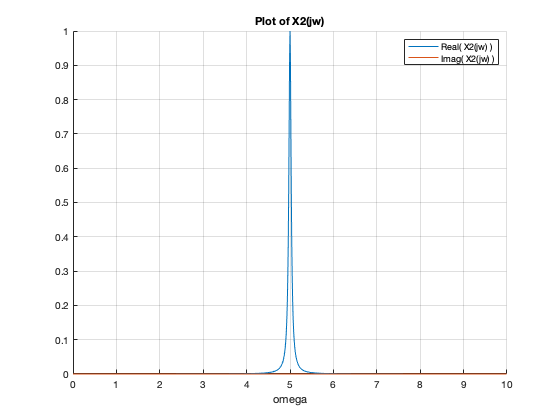

%4.2e Code
clf;
X2 = Y.*exp(1j*5*w);
% plot X2(jw)

figure(4);
hold on;
plot(t, real(X2)); grid;
plot(t, imag(X2));
title('Plot of X2(jw)'); legend('Real( X2(jw) )', 'Imag( X2(jw) )'); xlabel('omega');


hold off

(f). Using **abs** and **angle**, plot the magnitude and phase of **X** over the frequency range specified in **w**. For the same values of $\omega$, also plot the magnitude and phase of the

analytic expression you derived for $X(j\omega)$ in Part (a). Does your approximation  of the CTFT match what you derived analytically? If you plot the magnitude on

a logarithmic scale, using semilogy, you will notice that at higher frequencies the approximation is not as good as at lower frequencies. Since you have approximated

$x(t)$ with samples $x(n\tau)$, your approximation will be better for frequency components of the signal that do not vary much over time intervals of length $\tau$.

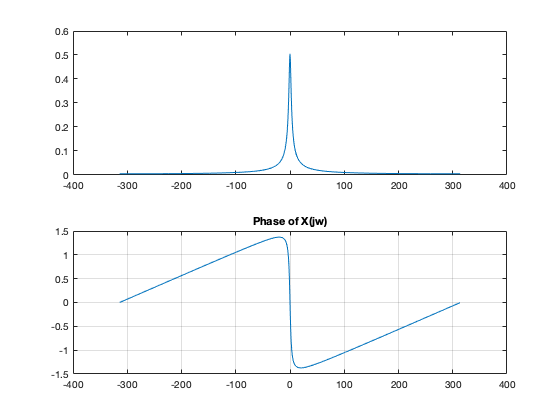

%4.2f Code
clf;


figure(5);
subplot(2,1,1); plot(w,abs(X));
subplot(2,1,2); plot(w,angle(X));
title('Magnitude of X(jw)'); grid;
title('Phase of X(jw)'); 

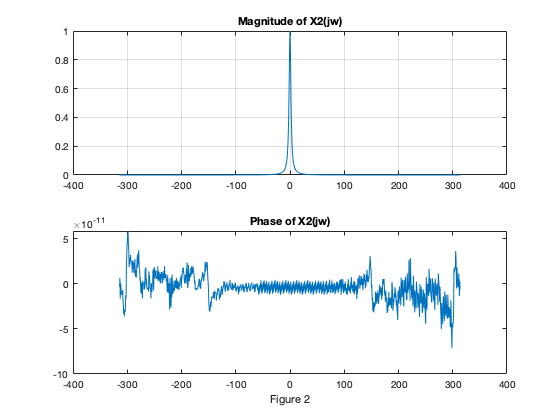

clf;


figure(6);
subplot(2,1,1);plot(w,abs(X2));title('Magnitude of X2(jw)');  grid;
subplot(2,1,2);plot(w,angle(X2)*57.3);title('Phase of X2(jw)'); xlabel('Figure 2');

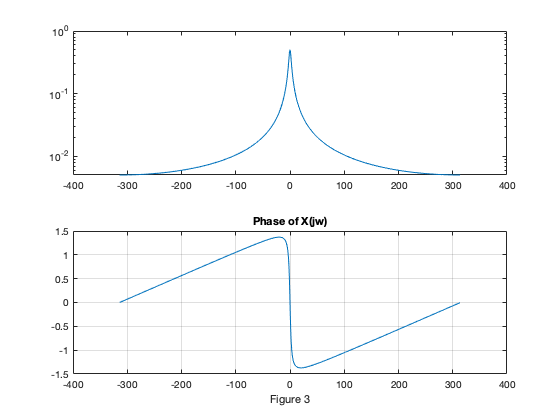

clf;
figure;
subplot(2,1,1); semilogy(w,abs(X));
subplot(2,1,2); plot(w,angle(X));
title('Magnitude of X(jw) in Log scale'); grid;
title('Phase of X(jw)'); xlabel('Figure 3');

(g). Plot the magnitude and phase of **Y** using **abs** and **angle**. How do they compare with **X**? Could you have anticipated this result?

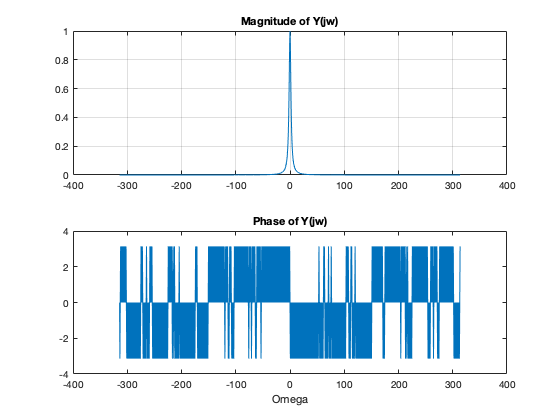

%4.2g Code
clf;

figure(7);
subplot(2,1,1); plot(w,abs(Y)); title('Magnitude of Y(jw)');    grid;
subplot(2,1,2); plot(w,angle(Y));title('Phase of Y(jw)');   xlabel('Omega');

## 4.3 Properties of the Continuous-Time Fourier Transform

In this exercise, you will enhance your understanding of the continuous-time Fourier transform (CTFT) by analyzing and manipulating audio signals in the frequency and time domains.

Audio signals in MATLAB are represented by vectors containing samples of the continuous-time audio signal. The sampling rate is assumed to be 8192 Hz, i.e., the audio

signal is sampled every $\Delta t=(1/8192)$ seconds. To be more precise, for an audio signal $y(t)$ sampled at 8192 Hz over the interval $0\le t \le N\Delta t$, the N-element vector **y** which

represents the audio signal is given by

                                            
$$y(n) = y((n - 1) \Delta t), \ \ \ n = 1,. . . , N .
$$


The function **sound** can then be used to play the signal on your computer's speaker. While this is a sampled representation of a continuous-time audio signal $y(t)$, if $y(t)$ is

zero otside the sampling interval and the sampling rate $f_s = 8192 $Hz is fast enough, then y can be considered an accurate representation of $y(t)$. For all the signals in this exercise,** y**

can be assumed to be an accurate representation of $y(t)$. To begin this exercise, you must first load a sample audio signal by typing

**>> load splat**

**>> y = y(1:8192);**

To verify that you have accurately loaded the audio data, and to convince yourself that the MATLAB vector y can accurately represent an audio signal, type

The function **fft** takes the sampled representation **y** and computes an approximation to the CTFT of $y(t)$, $Y(j\omega)$, at samples of $\omega$. If you type

**>> Y= fftshift(fft(y));**

then the vector **Y** contains an approximation to $Y(j\omega) $at **N** evenly spaced frequencies on the interval $-\pi f_s \le \omega < \pi f_s$. In fact, **Y** contains only approximate values of $cY(j\omega)$,

where c is a constant, but you should not worry about the approximation or the scaling for the purposes of this exercise. Refer to Exercise 4.2 for a more complete discussion of the

relationship between $Y(j\omega) $and Y. The function **fftshift** re-orders the output of **fft** so that the samples of $Y(j\omega) $ are ordered in **Y** from the most negative to most positive frequencies. 

Most of the properties that you associate with the CTFT can now be verified on the vector **Y**.

### Basic Problems

(a). Type **Y=fftshift(fft(y))** to calculate the Fourier transform vector **Y**. The corresponding frequency values can be stored in the vector **w** by typing

**>> w = [-pi:2*pi/N:pi-pi/N]*fs;**

Use **w** and **Y** to plot the magnitude of the continuous-time Fourier transform over the interval $-\pi f_s \le \omega < \pi f_s$.

The function **ifft** is the inverse operation of **fft**. For even length vectors, **fftshift** is its own inverse. For the vector **Y**, **N = 8192** and the inverse Fourier transform can be found

by typing

**>>y=ifft(fftshift(Y));**

**>>y=real(y);**

The **real** function is applied here because the original time-domain signal was known to be real. However, numerical roundoff errors in **fft** and **ifft** can introduce a very small

nonzero imaginary component to **y**. In general, the inverse CTFT is not necessarily a real signal, and the imaginary part may contain significant energy. The **real** function should

only be used on the output of **ifft** when you know the resulting signal must be real, e.g., an audio signal, and you have verified the imaginary part that you will be removing is

insignificant.

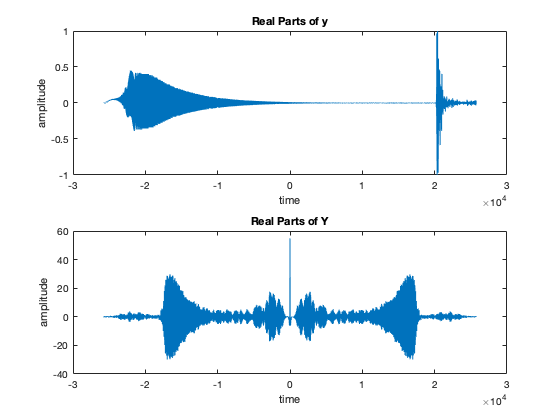

%4.3a
clf;

load splat.mat
y = y(1:8192);
N=8192;
fs=8192;
sound(y,N);
Y=fftshift(fft(y));
w = [-pi:2*pi/N:pi-pi/N]*fs;

figure(1);

subplot(2,1,1);plot(w,real(y));title('Real Parts of y');xlabel('time');ylabel('amplitude');
subplot(2,1,2);plot(w,real(Y));title('Real Parts of Y');xlabel('time');ylabel('amplitude');

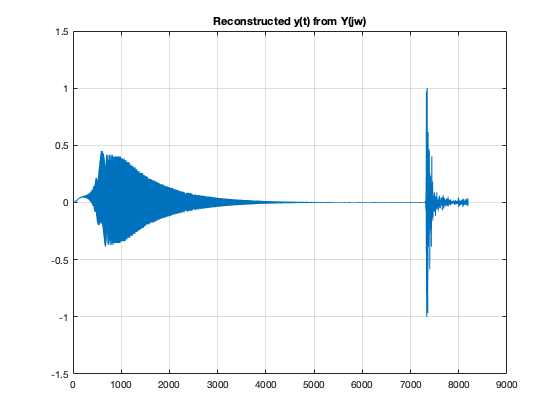

clf;
y=ifft(fftshift(Y));
y=real(y);
sound(y,fs);
plot(y); grid; title('Reconstructed y(t) from Y(jw)');

(b). Set **Y1=conj (Y)**, and store in **y1** the inverse Fourier transform of **Y1**. Use** real(y1) **to ensure **y1** is real. Play **y1** using **sound(y1 ,fs)**. Can you explain what you just heard, knowing how the inverse Fourier transform of $Y*(j\omega) $is related to $y(t)$?

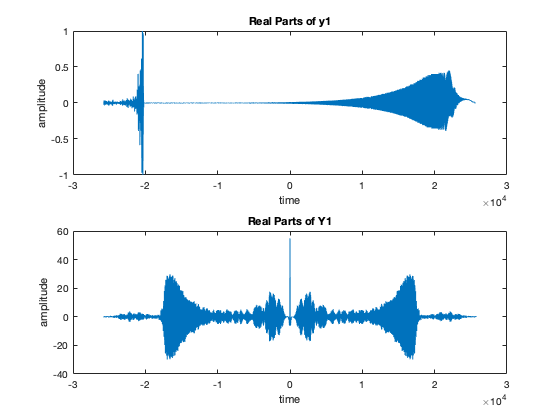

%4.3b
clf;
Y1 = conj(Y);

y1 = ifft(fftshift(Y1));
sound(y1,N);

figure(2);
subplot(2,1,1);plot(w,real(y1));title('Real Parts of y1');xlabel('time');ylabel('amplitude');
subplot(2,1,2);plot(w,real(Y1));title('Real Parts of Y1');xlabel('time');ylabel('amplitude');

### Intermediate Problems

The CTFT of $y(t)$ can be written in terms of its magnitude and phase as

                                        $Y(j\omega) =|Y(j\omega)|e^{j\phi(\omega)}$,

 where  $\phi(\omega) = \angle Y(j\omega)$. For many signals, either the phase or the magnitude alone can be used to construct a useful approximation of the signal $y(t)$. For instance, consider the

signals $y_2(t) $and $y_3(t) $ with CTFTs

                                        
$$Y_2(j\omega) = |Y(j\omega)| \ \ and  \ \  Y_3(j\omega)= e^{j\phi(\omega)}$$


(c). Demonstrate analytically that $ y_2(t)$ and$ y_3(t)$ will be real signals whenever $ y(t) $ is real.

%4.3c Code
clf;
phi_w = abs(Y);

y_analytically= Y.*exp(1j*phi_w);

y2_analytically =abs(y_analytically);
y3_analytically= exp(1j*phi_w);


(d). Construct a vector **Y2** equal to the magnitude of **Y**. Store in **y2** the inverse Fourier transform of **Y2**. Play this vector using sound.

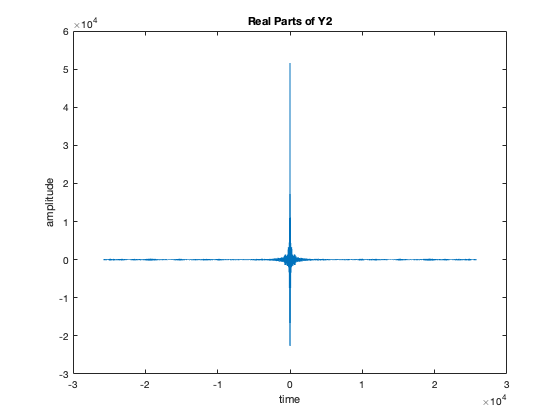

%4.3d Code
clf;
Y2=fftshift(fft(y2_analytically));

sound(real(Y2),N);

figure(4);
plot(w,real(Y2));title('Real Parts of Y2');xlabel('time');ylabel('amplitude');

(e). Construct a vector **Y3** which has the same phase as **Y**, but has magnitude equal to one for each frequency. Store in **y3** the inverse Fourier transform of **Y3**. Play this vector

using sound.

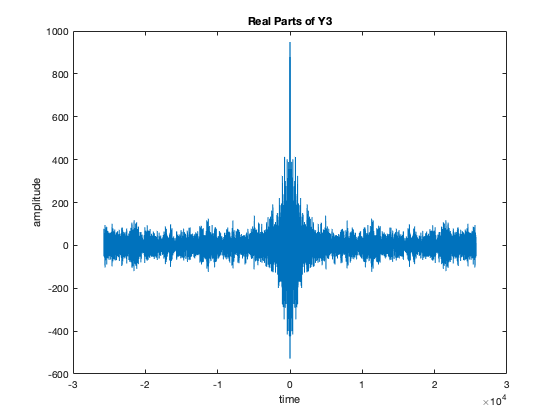

%4.3e Code

clf;
Y3=fftshift(fft(y3_analytically));

sound(real(Y3),N);

figure(5);
plot(w,real(Y3));title('Real Parts of Y3');xlabel('time');ylabel('amplitude');

(f). Based upon the two signals you just heard, which component of the Fourier transform would you say is most crucial for representing an audio signal: the magnitude or the

phase?

**Answer**

The magnitude is more crucial for representing the audio signals when Fourier transform is considered.

## 4.4 Time- and Frequency-Domain Characterizations of Systems

The impulse response $h(t)$ of an LTI system completely characterizes the system since the response $y(t)$ to any input$ x(t)$ is given by the convolution$ y(t) = h(t) *x(t)$. If the system is

stable, an equivalent representation of the system is given by its frequency response $H(j\omega)$. In this case the continuous-time Fourier transforms are related by $Y(j\omega) = H(j\omega) X(j\omega)$.

In this exercise, you will consider a number of stable LTI systems described by linear constant-coefficient differential equations. For these systems, you will be asked to calculate

their impulse and frequency responses. Although either the frequency response or the impulse response is sufficient to completely characterize an LTI system, you will learn that

it is sometimes advantageous to consider system properties in both the time and frequency domains.

### Basic Problems

These problems assume that you have completed Tutorial 4.1, on freqs. Consider the class of causal LTI systems given by

                                                                                                    (4.11)

            
$$\frac{dy(t)}{dt}+a_0 y(t)=a_0 x(t)$$


where $a_0 > 0 $ guarantees stability. Define System **I** to be the system satisfying Eq. (4.11)

for $a_0 = 3$ and define System **II** to be the system for $a_o = 1/3.$

(a). Analytically derive the frequency response for the stable LTI system corresponding to Eq. (4.11). Also determine the magnitude and phase of this frequency response.

**4.4a Analysis**

for the System I, $a_0 = 3$ we have:

       
$$\frac{dy(t)}{dt}+3 y(t)=3x(t)$$


and the frequency response of the System I :


$$H(j\omega)= \frac{3}{3+j\omega}$$


for the System II, $a_0 = 1/3$ we have:

       
$$\frac{dy(t)}{dt}+\frac{y(t)}{3}= \frac{x(t)}{3}$$


and the frequency response of the System I :


$$H(j\omega)= \frac{1/3}{1/3+j\omega}= \frac{1}{1+3j\omega}$$


(b). Define **w=linspace(0, 10)**. Use freqs to calculate the frequency response of **Systems I and II **at the frequencies in w. Plot the magnitude of these two responses in a single

figure. Do the magnitude plots agree with your analytic expression for the frequency response magnitude?

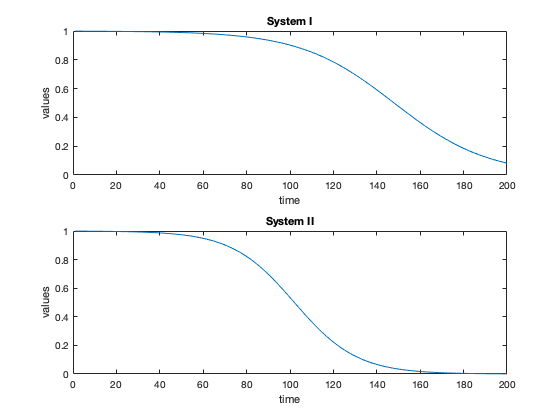

%4.4b Code
clf;
w=linspace(0, 10);
a1=[1 3];
a2=[1 1/3];
b1= 3;
b2=1/3;

fr1= freqs(b1,a1);
fr2= freqs(b2,a2);

figure(1);
subplot(2,1,1);plot(real(fr1)); xlabel('time'); ylabel('values'); title('System I');
subplot(2,1,2);plot(real(fr2)); xlabel('time'); ylabel('values'); title('System II');

(c). Use the function **impulse** described in Tutorial 3.3 to calculate the impulse response of** Systems I and II** at time samples defined by the **vector t=linspace(0,5).**

%4.4c Code
clf;
t= linspace(0,5);
% I didn't use the equation x, from tutorial 3.3 corrected that
x=cos(t);
% Correction of a and b paramaters for lsim func
a1=[1 3];
b1=[3];
a2=[3 1];
b2=[1];

lr1=lsim(b1,a1,x,t);
lr2=lsim(b2,a2,x,t);

figure(2);
subplot(2,1,1);plot(lr1); xlabel('time'); ylabel('values'); title('System I');
subplot(2,1,2);plot(lr2); xlabel('time'); ylabel('values'); title('System II');

(d). What is the relationship between the rate at which the impulse response decays (with time) and the rate at which the frequency response magnitude decays (with

frequency)? What CTFT property explains this relationship?

**4.4d Analysis**

 The impulse response decays (with time) and the rate at which the frequency response magnitude decays (with frequency) are proportional and Parseval property can explains this relationship 